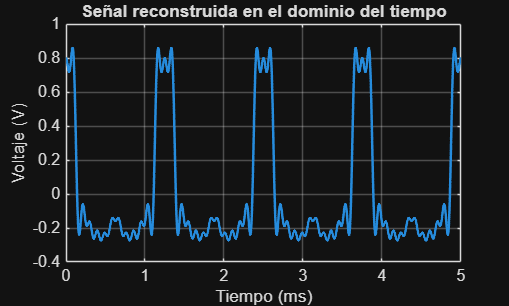

clc;
clear;
close all;

% Vector de tiempo (5 ms)
t = 0:1e-6:(5e-3-1e-6);

v = 0.385048112*cos(2*pi*800*t) + ...   
    0.295471092*cos(2*pi*1600*t) + ...  
    0.143058938*cos(2*pi*2400*t) + ...  
    0.096719713*cos(2*pi*3200*t) - ...  
    0.045239208*cos(2*pi*4800*t) - ... 
    0.088209426*cos(2*pi*5600*t) - ...  
    0.076827199*cos(2*pi*6400*t) - ...  
    0.042219686*cos(2*pi*7200*t) + ...  
    0.033536289*cos(2*pi*8800*t) + ...  
    0.050759227*cos(2*pi*9600*t) + ...  
    0.048474685*cos(2*pi*10400*t);     

% Dominio del tiempo
figure;
plot(t*1000, v, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo (ms)');
ylabel('Voltaje (V)');
title('Señal reconstruida en el dominio del tiempo');

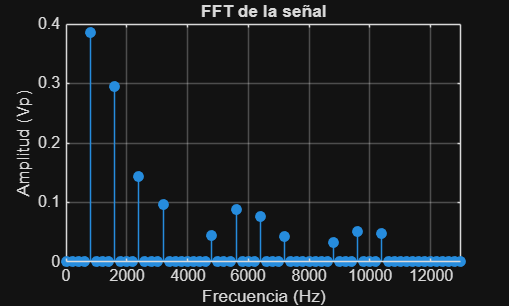


% Dominio de la frecuencia

Fs = 1/(t(2)-t(1));
N = length(v);

V = fft(v-mean(v));
P2 = abs(V)/N;
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:N/2)/N;

figure;
stem(f,P1,'filled');
grid on;
xlabel('Frecuencia (Hz)');
ylabel('Amplitud (Vp)');
title('FFT de la señal');
xlim([0 13000]);